# PROCESS CONTROL ASSIGNMENT 2

Name: NSENGUMUKIZA IRENE

MATRIC N0.: G2303789D

# LQR applied to aircraft

**(i) Design \quad 3 LQR \quad controllers for a fixed**$ $\gamma=0.01$ \quad and \quad $\rho=0.1,10,100$.$

gamma = 1e-2; 
rhos = [1e-1, 10, 1e2];
figure;
hold on;
for rho = rhos
A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
G = [1 0 0; 0, gamma*1, 0];
H = [0; 0];
Q = G' * G;
R = H'* H + rho;
N = G'* H;
[K, P, poles] = lqr(A, B, Q, R, N);
GO = ss(A, B, K, 0);
[GainMargin, PhaseMargin, GainCrossOverFreq, PhaseCrossOverFreq] = margin(GO);
sprintf('rho = %d and gamma = %d', rho, gamma)
disp('------------------------------------')
disp(PhaseMargin)
bode(GO)
end

ans = 'rho = 1.000000e-01 and gamma = 1.000000e-02'

------------------------------------


   66.6468



ans = 'rho = 10 and gamma = 1.000000e-02'

------------------------------------


   70.2300



ans = 'rho = 100 and gamma = 1.000000e-02'

------------------------------------


   74.9383



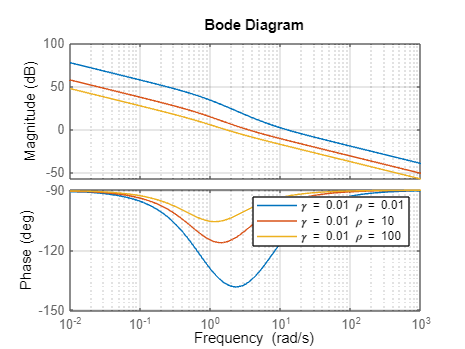

grid on;
hold off;
legend('\gamma = 0.01 \rho = 0.01', '\gamma = 0.01 \rho = 10', '\gamma = 0.01 \rho = 100')

**(ii). Design 3 LQR controllers for a fixed **$$\rho=0.01$ and $\gamma=0.01,0.1,1$$

rho = 1e-2; % Example values for gamma
gamma = [1e-2, 0.1, 1]; % Example values for rho
figure;
hold on;
for gam = gamma
A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
G = [1 0 0; 0, gam*1, 0];
H = [0; 0];
Q = G' * G;
R = H'* H + rho;
N = G'* H;
[K2, P2, poles2] = lqr(A, B, Q, R, N);
sprintf('rho = %d and gamma = %d', rho, gam)
disp('------------------------------------')
GO = ss(A, B, K2, 0);
[GainMargin, PhaseMargin, GainCrossOverFreq, PhaseCrossOverFreq] = margin(GO);
disp('Phase margin: ')
disp(PhaseMargin)
disp('------------------------------------')
bode(GO);
% step(GO);
end

ans = 'rho = 1.000000e-02 and gamma = 1.000000e-02'

------------------------------------


Phase margin: 


   65.7652



------------------------------------


ans = 'rho = 1.000000e-02 and gamma = 1.000000e-01'

------------------------------------


Phase margin: 


   74.3118



------------------------------------


ans = 'rho = 1.000000e-02 and gamma = 1'

------------------------------------


Phase margin: 


   72.7870



------------------------------------


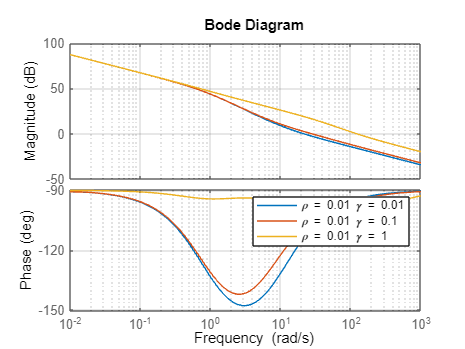

grid on;
hold off;
legend('\rho = 0.01 \gamma = 0.01', '\rho = 0.01 \gamma = 0.1', '\rho = 0.01 \gamma = 1')

**(iii) Determine the phase margins for the LQR controllers designed in Part 2(a)(i)and (ii).**

for each controller I used to compute phase margin at design point since I was using loop to iterate over them, the easiest way was to calculate phase margin of each controller at that point of designing.

**For the controllers designed in part 1**


$$\rho = 0.1 \quad \gamma = 0.01 \quad Phase -margin= 66.6468 \degree \\
\rho = 10 \quad \gamma = 0.01 \quad Phase -margin= 70.230 \degree \\
\rho = 100 \quad \gamma = 0.01 \quad Phase -margin= 74.9383 \degree \\
$$


**Effect of increasing **$$\rho$$

Increasing $$\rho$$ With $$\gamma$$ held constant at 0.01 leads to an increase in the phase margin. This indicates that increasing the weight on the state error relative to the control effort can make the system more robust to phase changes, as a higher phase margin indicates a larger buffer before the system reaches instability.

**For controllers designed in part 2**


$$\rho = 0.01 \quad \gamma = 0.01 \quad Phase -margin= 65.7652 \degree \\
\rho = 0.01 \quad \gamma = 0.1 \quad Phase -margin= 74.3118 \degree \\
\rho = 0.01 \quad \gamma = 1 \quad Phase -margin= 72.7870 \degree \\$$


**Effect of increasing **$$\gamma$$

Initially increasing $$\gamma$$ from 0.01 to 0.1 increases the phase margin, but further increasing $$\gamma$$ to 1 results in a slight decrease in the phase margin. This suggests that there might be an optimal range for 

$$\gamma$$ that maximizes the phase margin. This behavior is typical as tuning parameters may have non-linear effects on system stability metrics.

## Nyquist plot

`(i) Select `$$ Q = I_{2 \times 2}, R = 1, \rho = 0.1, \gamma = 1$$`. Plot the Nyquist plot of the loop transfer function`

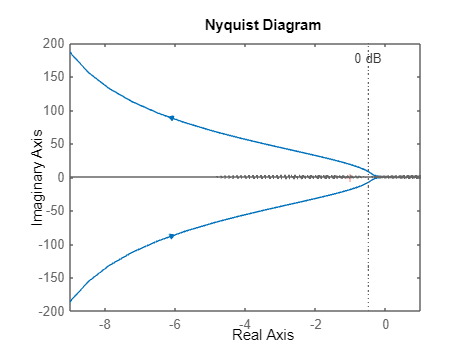

gamma = 1; % Example values for gamma
rho = 1e-1; % Example values for rho

A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
G = [1 0 0; 0, gamma*1, 0];
H = [0; 0];
Q = G' * G;
R = H'* H + rho;
N = G'* H;
K = lqr(A, B, Q, R, N);
GO = ss(A, B, K, 0);
figure;
nyquist(GO);
grid on;

`(ii) Under state feedback u = -Kx, the closed-loop dynamics are given by`


$$\dot{x} = (A - BK)x$$


`and the closed-loop poles are the eigenvalues of `$A - BK$`. compute a state feedback gain matrix `$K$` that assigns these poles to any locations. closed loop poles `$p = -1, -2, -3$**.**

A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];

% Define the desired closed-loop poles
p = [-1, -2, -3];

% Compute the state feedback gain matrix K using the place function
K = place(A, B, p)

K =    -0.0060   -0.0065   -0.8975


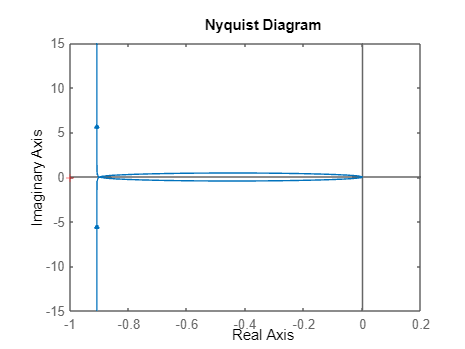

GO = ss(A, B, K, 0);
figure;
nyquist(GO);

**(iii) Compare the Nyquist plots obtained in (i) and (ii) in terms of whether these plots enter within a circle of radius 1 centered at -1. What can you conclude about the robustness of the 2 design methods against multiplicative uncertainty?**

The Nyquist plots for two control design methods were examined for robustness against multiplicative uncertainty by observing their behavior around a circle of radius 1 centered at -1 in the complex plane. Both plots avoided encircling the critical point, indicative of stable closed-loop systems. The first design method's Nyquist plot shows a conservative approach with a significant margin from the critical stability boundary. In contrast, the second method's plot, though more expansive, similarly does not intersect with the defined circle, suggesting an adequate stability margin.

Neither design's Nyquist plot enters the critical circle, pointing towards an inherent robustness to uncertainties that could perturb the system's poles within this region. While this suggests that both methods offer stable control strategies resistant to certain levels of uncertainty, a full assessment of robustness would require additional analysis, such as evaluating gain and phase margins, transient responses, and overall system performance objectives.

## Step Response

(i) Plot on the same graph, the step responses to roll angle setpoint command of  r = 1  rad for the 3 LQR state feedback controllers designed in Part 2(a) (i) for $\rho$ = 0.1, 10, 100  and $\gamma = 0.01$

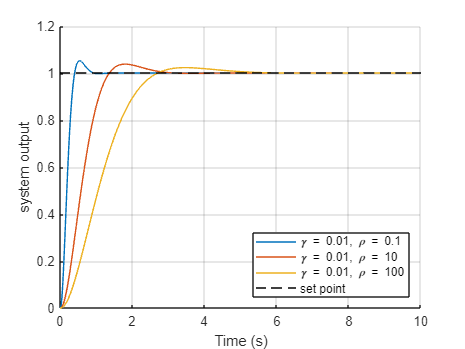

A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
gamma = 1e-2; % Fixed value for gamma
rhos = [1e-1, 1e1, 1e2]; % Iterating over these values for rho
G = [1 0 0; 0, gamma, 0];
H = [0; 0];
Q = G' * G;

% Define the reference set point
r = [1; 0; 0]; % Reference for the first state

% Simulation parameters
dt = 0.01; % Time step (s)
T = 10; % Total simulation time (s)
time = 0:dt:T; % Time vector

figure;
hold on;

% Iterate over the different values of rho
for idx = 1:length(rhos)
    R = rhos(idx); % Use the current rho value for R

    % Solve for the LQR gain matrix K
    [K, ~, ~] = lqr(A, B, Q, R);
    % Initial conditions
    x = zeros(3,1); % Initialize state

    % Preallocate state history for plotting
    x_history = zeros(3, length(time));

    % Closed-loop simulation
    for i = 1:length(time)
        % Control law with reference tracking
        u = -K*(x - r);

        % System dynamics
        x_dot = A*x + B*u;

        % Euler integration for state update
        x = x + x_dot * dt;

        % Store state history
        x_history(:, i) = x;
    end

    % Plotting for the current rho value
    plot(time, x_history(1,:), 'DisplayName', ['\gamma = ', num2str(gamma), ', \rho = ', num2str(rhos(idx))]);
end

% Plot reference line
plot(time, r(1)*ones(size(time)), 'k--', 'DisplayName', 'set point');

% Enhance plot
% title('Open-loop gain for several values of \rho and \gamma = 0.01');
xlabel('Time (s)');
ylabel('system output');
legend('show');
legend('Location', 'southeast');
grid on;
hold off;

`(ii) Plot on the same graph, the step responses to roll angle setpoint command of r=1 rad for the 3 LQR state feedback controllers designed in Part 2(a) (ii) for `$\gamma$` = 0.01, 0.1, 1.`

% Define system matrices
A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
rho = 1e-2; 
gamma = [1e-2, 1e-1, 1]; 
R = rho; 
r = [1; 0; 0];

% Simulation parameters
dt = 0.01; % Time step (s)
T = 6; % Total simulation time (s)
time = 0:dt:T; % Time vector

% Preallocate figure for plots
figure;
hold on;

% Iterate over the different values of rho
for idx = 1:length(gamma)
    G = [1 0 0; 0, gamma(idx), 0];
    Q = G' * G;
    % Solve for the LQR gain matrix K
    [K, ~, ~] = lqr(A, B, Q, R);

    fprintf("%d : K: ", idx);
    disp(K)
    disp('________________________________________')
    % Initial conditions
    x = zeros(3,1); % Initialize state

    % Preallocate state history for plotting
    x_history = zeros(3, length(time));

    % Closed-loop simulation
    for i = 1:length(time)
        % Control law with reference tracking
        u = -K*(x - r);

        % System dynamics
        x_dot = A*x + B*u;

        % Euler integration for state update
        x = x + x_dot * dt;

        % Store state history
        x_history(:, i) = x;
    end

    % Plotting for the current rho value
    plot(time, x_history(1,:), 'DisplayName', ['\gamma = ', num2str(gamma(idx)), ', \rho = ', num2str(R)]);
end

1 : K: 

  -10.0000   -1.1264    0.3788



________________________________________


2 : K: 

  -10.0000   -1.5184    0.4882



________________________________________


3 : K: 

  -10.0000  -10.0186    2.0025



________________________________________


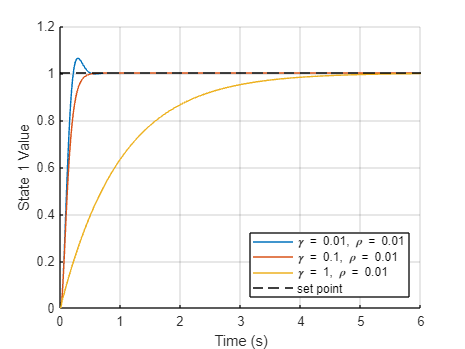


% Plot reference line
plot(time, r(1)*ones(size(time)), 'k--', 'DisplayName', 'set point');
legend('Location', 'southeast');
% Enhance plot
% title('State 1 Trajectories with LQR Control and Reference Tracking for Different \rho');
xlabel('Time (s)');
ylabel('State 1 Value');
legend('show');
grid on;
hold off;

**(iii) Compare the effect of the step responses (speed and overshoot) for variations in **$\rho$**  and **$\gamma$

**For varying **$$\rho$$

**Low** 

$$\rho$$ (0.01): The response quickly rises to the setpoint with some initial overshoot and oscillations, indicating a potentially more aggressive control action with less weight on control effort (since $$\rho$$ is in the denominator of the control weight in the LQR cost function). 

**Medium**

$$\rho$$ (10): The response is slower, with no overshoot, showing a more conservative control action where both state errors and control effort are more balanced.

**High **

$$\rho$$ (100): The response is the slowest, with the least aggressive control action, indicating a high weight on minimizing control effort compared to state errors.

**For fixed **$$\rho$$

**Low** $$\gamma$$ (0.01): Similar to the low 

$$\rho$$ case, the system responds quickly and with an initial overshoot, indicating an aggressive control action that prioritizes state error over control effort.

**Medium** 

$$\gamma$$ (0.1): The response is slower and with no overshoot, suggesting a balance between state error and control effort.

**High **

$$\gamma$$ (1): The response is very slow and the least aggressive, prioritizing control effort significantly over state error minimization.

**Comparative Analysis**

Speed of Response

 Lower values of $$\rho$ $ and $$\gamma$$ leads to faster system responses. This is because a lower value in the LQR cost function denominator implies less emphasis on the control effort, allowing the controller to act more aggressively to minimize state errors. 

Overshoot

Lower values of $$\rho$$ and $$\gamma$$ results in more overshoot, which is typical for more aggressive control strategies. Higher values tend to suppress overshoot, indicating a more cautious approach to control action.

Stability and Robustness

While not directly observable from these plots, systems with higher values of 

$$\rho$$ and $$\gamma$$ are likely to be more robust to disturbances and model uncertainties since they apply control more gently, avoiding sharp reactions that could be destabilizing in the presence of real-world uncertainties.

Control Effort

A higher value of $$\rho$$ and $$\gamma$$ implies a controller that puts more emphasis on reducing control effort, which can be important for energy savings or when dealing with actuator limitations.

## Set-Point Tracking

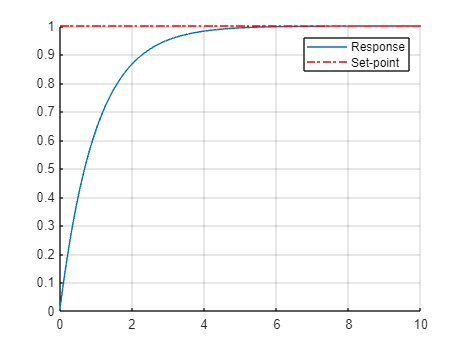

% Define system matrices

A = [0 1 0; 0 -0.875 20; 0 0 -50];
B = [0; 0; 50];
C = [1 0 0;0 1 0];
Q = C' * C;
R = 1; % As provided from the previous calculations

% Compute the LQR gain matrix K
[K, ~, ~] = lqr(A, B, Q, R);

r = 1; 

% Simulation parameters
dt = 0.01; % Time step (s)
T = 10; % Total simulation time (s)
time = 0:dt:T; % Time vector
x_history = zeros(3, length(time));
% Preallocate figure for plots
figure;
hold on;

x = zeros(3,1); % Initialize state to match the system dimension

for i = 1:length(time)
    % Control law with reference tracking and pre-compensatory gain
    u = -K * (x - r);
    % System dynamics
    Ccl = [1 0 0];
    Bcl = [1; 0; 0];
    e = -1 / (Ccl*inv(A - B*K)*Bcl);
    % x_dot = A * x + B * u + Bcl'*r*e;
    x_dot = (A - B*K)*x + Bcl*r*e;
    % Euler integration for state update
    x = x + x_dot * dt;
    
    % % Store state history
    x_history(:, i) = x;
end
plot(time, x_history(1,:));
plot(time, repmat([1], 1, size(x_history(1,:), 2)), 'r-.');
grid on
legend('Response', 'Set-point')